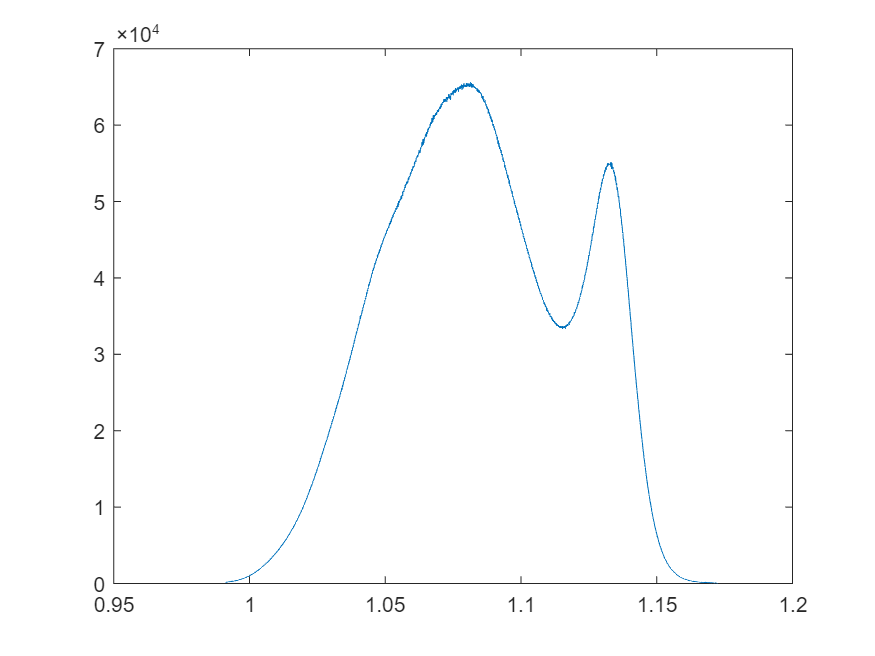

clear; clc;
%Original spectral interference signal
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
load('Wavelength.mat','Wavelength');
% figure(1);plot(1:2048,Wavelength);
% figure(2);plot(Wavelength,Spectrum);
% figure(3);plot(Wavelength,RawData(:,1));
%波数空间采样及线性矫正
%将波长和光谱强度逆序排列
% spectrum = RawData(:,1);
intensity = zeros(1,length(Spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = Spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
figure(4);plot(sigma_inter,intensity_inter);

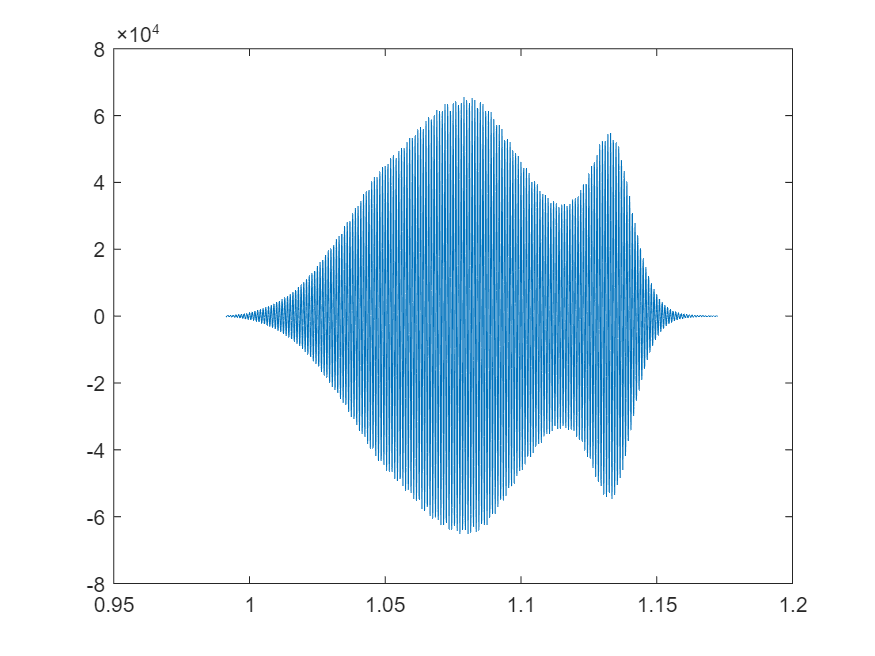

%光谱干涉信号S(\sigma) = A(\sigma)*cos(4\pi*(z-z0)*\sigma-4\pi*T*n(\sigma)*\sigma)
spec_signal = intensity_inter;

%设置z = 1000um
z1 = 500;
z0 = 0;
interference_signal = spec_signal.*cos(4*pi*(z1-z0).*sigma_inter);%+2*spec_signal;
figure(5);plot(sigma_inter,interference_signal);

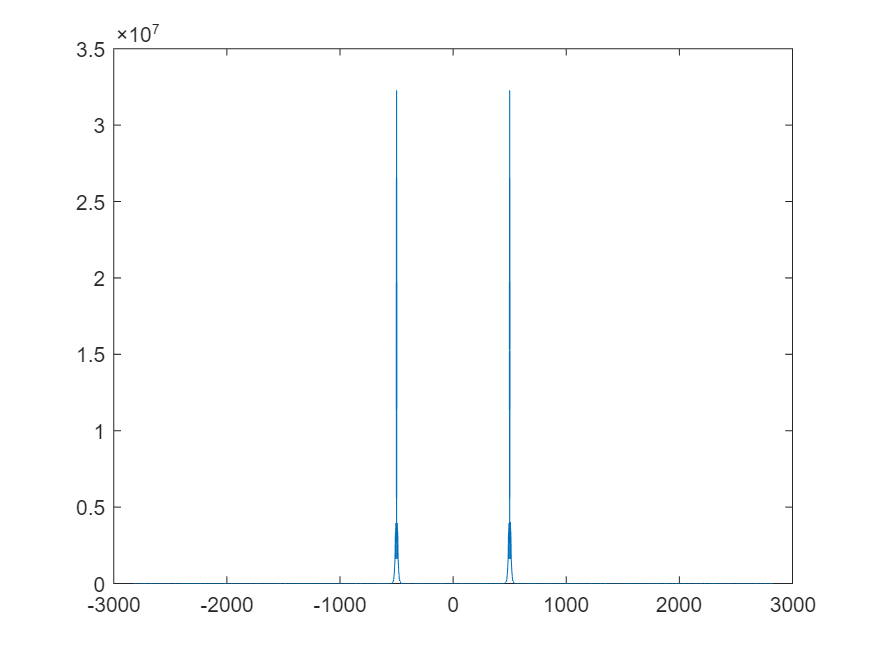

%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(interference_signal,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
figure(6);plot(z,intensity_fft);

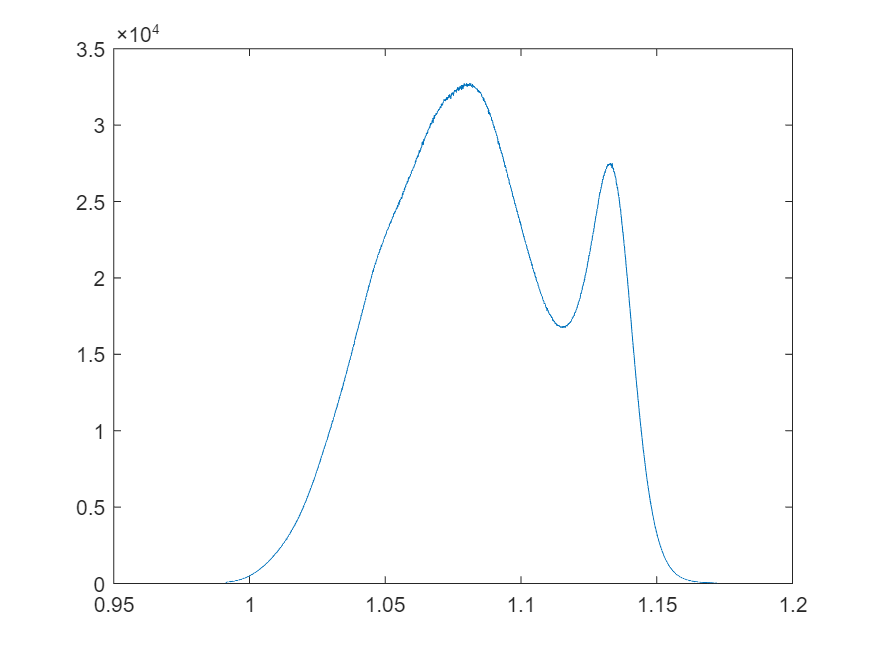

% figure(7);plot(z,unwrap(angle_fft));

%傅里叶逆变换
ifft_signal = interference_signal(length(interference_signal)/2+1:end);
z = z(length(z)/2+1:end);
Nfft = 2^20;
ifft_signal = ifft(ifft_signal,Nfft);
interference_signal = ifftshift(ifft_signal);
deltaz = (z(end)-z(1))/(length(z)-1);
deltasigma = 1/(2*Nfft*deltaz);
sigma = (1:Nfft)*deltasigma;
intensity_ifft = abs(interference_signal);
angle_ifft = angle(interference_signal);
%坐标变换
sigma = sigma-sigma(end)/2+sigma_inter(1);
[~, indix_min] = min(abs(sigma-sigma_inter(1)));
[~, indix_max] = min(abs(sigma-sigma_inter(end)));
figure(6);plot(sigma(indix_min:indix_max),intensity_ifft(indix_min:indix_max));

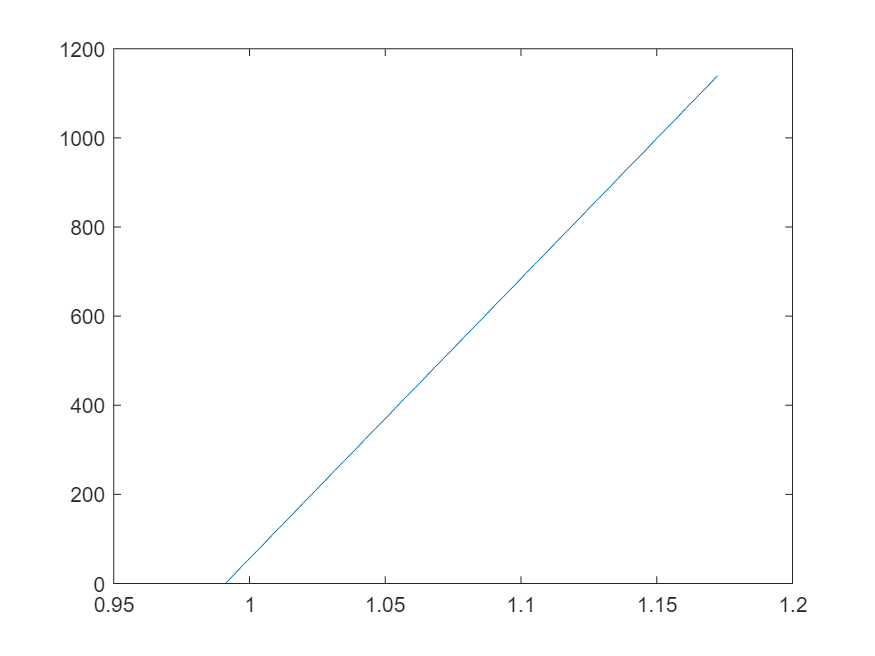

figure(7);plot(sigma(indix_min:indix_max),unwrap(angle_ifft(indix_min:indix_max)));